# Robotics Midterm Test - 2019-04-29

## Exercise 2: PRP Robot

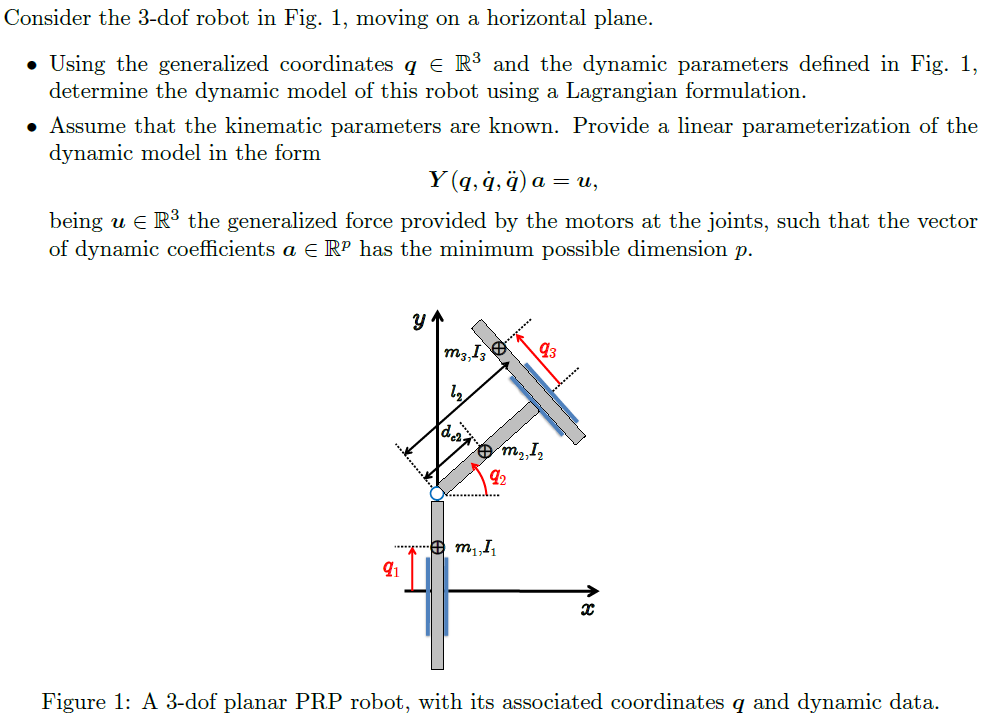

### Automatic attempt

% clear;clc
% sigma = [1,0,1];
% n = length(sigma);
% q = sym('q', [1 n]);
% qd = sym('qd', [1 n]);
% qdd = sym('qdd', [1 n]); 
% d = sym('d', [1 n]);
% a = sym('a', [1 n]);
% l = sym('l', [1 n]);
% m = sym('m', [1 n]);
% I = sym('I', [1 n]);
% 
% %       alpha   a   d   theta
% dhTable = [pi/2  0    q(1)    0;
%            -pi/2  l(2) 0       q(2);
%            0      0   q(3)    0]
% 
% 
% % % L(n)=LINK([theta D A alpha Sigma(optional) Offset(optional)])
% % % Must only specify either THETA or D
% % 
% % L(1) = Link('a', 0, 'alpha', 0*pi/2,  'theta', pi/2,'qlim',[0,10]); % Prismatic
% % L(2) = Link('a', 10, 'alpha', -pi/2, 'd', 0,'qlim',[0,pi]); % Revolute
% % L(3) = Link('a', 0, 'alpha', 0,     'theta', 0,'qlim',[0,10]); % Prismatic
% % prpRobot = SerialLink(L, 'name', 'PRP_Robot ')
% % prpRobot.teach
% % 
% rc = [0,0,q(1);
%     d(2),0,0;
%    0,0,q(3)].'
% I = sym(zeros(3,3,n));
% %rc = []
% for i = 1:n
%  %   rc = [rc [-l(i)+d(i); 0; 0]];
%     I(:,:,i) = diag(sym(strcat({'Ixx','Iyy','Izz'},int2str(i))));
% end
      

% % M = getM(dhTable, sigma, qd, rc,m,I)
% % %% Cannot get the proper result


### Manual Attempt

% This part is isolated from previous section
clear;clc

syms k q1(t) q2(t) q3(t)
sigma = [1,0,1];
n = length(sigma);
q = sym('q', [1 n],'real');
qd = sym('qd', [1 n],'real');
qdd = sym('qdd', [1 n],'real'); 

% Md=sym('Md', [n n],'real');
% Td=qd*Md*qd'
% Md_ = getInertiaMatrixFromKE(Td,qd) dont work
d = sym('d', [1 n],'real');
l = sym('l', [1 n],'real');
m = sym('m', [1 n],'real');
I = sym('I', [1 n],'real');


%Insert manually the global positions of the centers of mass
pc(:,1) = [0 q1];
pc(:,2) = [d(2)*cos(q2), q1+k+d(2)*sin(q2)];
pc(:,3) = [l(2)*cos(q2)-q3*sin(q2), q1+k+l(2)*sin(q2)+q3*cos(q2)]

$$pc = \left(\begin{array}{ccc} 0 & d_{2}\,\cos\left(q_{2}\left(t\right)\right) & l_{2}\,\cos\left(q_{2}\left(t\right)\right)-\sin\left(q_{2}\left(t\right)\right)\,q_{3}\left(t\right)\\ q_{1}\left(t\right) & k+q_{1}\left(t\right)+d_{2}\,\sin\left(q_{2}\left(t\right)\right) & k+q_{1}\left(t\right)+l_{2}\,\sin\left(q_{2}\left(t\right)\right)+\cos\left(q_{2}\left(t\right)\right)\,q_{3}\left(t\right) \end{array}\right)$$

vc = diff(pc,t)

$$vc = \left(\begin{array}{ccc} 0 & -d_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & -\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)-\cos\left(q_{2}\left(t\right)\right)\,q_{3}\left(t\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)-l_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \frac{\partial }{\partial t}q_{1}\left(t\right) & \frac{\partial }{\partial t}q_{1}\left(t\right)+d_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & \cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)+\frac{\partial }{\partial t}q_{1}\left(t\right)-\sin\left(q_{2}\left(t\right)\right)\,q_{3}\left(t\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)+l_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}\right)$$

% Substitute the literals just for visualization, as we don't need to
% derivate
vc=subs(vc, [diff(q1(t), t), diff(q2(t), t), diff(q3(t), t)], qd);

vc=subs(vc, [q1,q2,q3], q);
w =[0, qd(2), qd(2)].';
for i=1:n
 T(i) = (1/2)*m(i)*(vc(:,i).'*vc(:,i)) + (1/2)*w(i)*I(i)*w(i);
end
KE = sum(T.')

$$KE = \frac{I_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{I_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{2}\,\left({\left({\mathrm{qd}}_{1}+d_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}+{d_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}\right)}{2}+\frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,\left({\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{3}\,\cos\left(q_{2}\right)+l_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)-q_{3}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}+{\left({\mathrm{qd}}_{3}\,\sin\left(q_{2}\right)+q_{3}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)+l_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}\right)}{2}$$

% Get the coeficients of the terms. That builds the M matrix
M = getInertiaMatrixFromKE(KE,qd)

$$M = \begin{array}{l} \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & \sigma_{1} & m_{3}\,\cos\left(q_{2}\right)\\ \sigma_{1} & m_{2}\,{d_{2}}^{2}+m_{3}\,{l_{2}}^{2}+m_{3}\,{q_{3}}^{2}+I_{2}+I_{3} & l_{2}\,m_{3}\\ m_{3}\,\cos\left(q_{2}\right) & l_{2}\,m_{3} & m_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=d_{2}\,m_{2}\,\cos\left(q_{2}\right)+l_{2}\,m_{3}\,\cos\left(q_{2}\right)-m_{3}\,q_{3}\,\sin\left(q_{2}\right) \end{array}$$

### Dynamic parameters identification

From the final expression of the Robot dynamic model , it's possible to extract the dynamic parameters, agrouping constant terms.

% It might take a while
[Msubs, dynamicParameters, a] = getDynamicParameters(M,q',l)

>> Getting dynamic coefficients. Might take a while...


params1term = 1×5 logical array
   0   1   1   1   1


MSubs First iteration


$$Msubs = \left(\begin{array}{ccc} {\mathrm{aa}}_{1} & {\mathrm{aa}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{aa}}_{3}\,l_{2}\,\cos\left(q_{2}\right)-{\mathrm{aa}}_{3}\,q_{3}\,\sin\left(q_{2}\right) & {\mathrm{aa}}_{3}\,\cos\left(q_{2}\right)\\ {\mathrm{aa}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{aa}}_{3}\,l_{2}\,\cos\left(q_{2}\right)-{\mathrm{aa}}_{3}\,q_{3}\,\sin\left(q_{2}\right) & {\mathrm{aa}}_{3}\,{l_{2}}^{2}+{\mathrm{aa}}_{3}\,{q_{3}}^{2}+I_{2}+I_{3}+{\mathrm{aa}}_{2}\,d_{2} & {\mathrm{aa}}_{3}\,l_{2}\\ {\mathrm{aa}}_{3}\,\cos\left(q_{2}\right) & {\mathrm{aa}}_{3}\,l_{2} & {\mathrm{aa}}_{3} \end{array}\right)$$

MSubs second iteration (before re-replacement)


$$Msubs = \left(\begin{array}{ccc} {\mathrm{aa}}_{1} & {\mathrm{aa}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{aa}}_{3}\,l_{2}\,\cos\left(q_{2}\right)-{\mathrm{aa}}_{3}\,q_{3}\,\sin\left(q_{2}\right) & {\mathrm{aa}}_{3}\,\cos\left(q_{2}\right)\\ {\mathrm{aa}}_{2}\,\cos\left(q_{2}\right)+{\mathrm{aa}}_{3}\,l_{2}\,\cos\left(q_{2}\right)-{\mathrm{aa}}_{3}\,q_{3}\,\sin\left(q_{2}\right) & {\mathrm{aa}}_{3}\,{l_{2}}^{2}+{\mathrm{aa}}_{3}\,{q_{3}}^{2}+{\mathrm{aa}}_{6} & {\mathrm{aa}}_{3}\,l_{2}\\ {\mathrm{aa}}_{3}\,\cos\left(q_{2}\right) & {\mathrm{aa}}_{3}\,l_{2} & {\mathrm{aa}}_{3} \end{array}\right)$$

$$Msubs = \left(\begin{array}{ccc} a_{1} & a_{2}\,\cos\left(q_{2}\right)+a_{3}\,l_{2}\,\cos\left(q_{2}\right)-a_{3}\,q_{3}\,\sin\left(q_{2}\right) & a_{3}\,\cos\left(q_{2}\right)\\ a_{2}\,\cos\left(q_{2}\right)+a_{3}\,l_{2}\,\cos\left(q_{2}\right)-a_{3}\,q_{3}\,\sin\left(q_{2}\right) & a_{3}\,{l_{2}}^{2}+a_{3}\,{q_{3}}^{2}+a_{4} & a_{3}\,l_{2}\\ a_{3}\,\cos\left(q_{2}\right) & a_{3}\,l_{2} & a_{3} \end{array}\right)$$

$$Msubs = \left(\begin{array}{ccc} a_{1} & a_{2}\,\cos\left(q_{2}\right)+a_{3}\,l_{2}\,\cos\left(q_{2}\right)-a_{3}\,q_{3}\,\sin\left(q_{2}\right) & a_{3}\,\cos\left(q_{2}\right)\\ a_{2}\,\cos\left(q_{2}\right)+a_{3}\,l_{2}\,\cos\left(q_{2}\right)-a_{3}\,q_{3}\,\sin\left(q_{2}\right) & a_{3}\,{l_{2}}^{2}+a_{3}\,{q_{3}}^{2}+a_{4} & a_{3}\,l_{2}\\ a_{3}\,\cos\left(q_{2}\right) & a_{3}\,l_{2} & a_{3} \end{array}\right)$$

$$dynamicParameters = \left(\begin{array}{c} m_{1}+m_{2}+m_{3}\\ d_{2}\,m_{2}\\ m_{3}\\ m_{2}\,{d_{2}}^{2}+I_{2}+I_{3} \end{array}\right)$$

$$a = \left(\begin{array}{cccc} a_{1} & a_{2} & a_{3} & a_{4} \end{array}\right)$$

% Torque full expression
MCs = getCs(Msubs,q',qd')

>> Getting  the Christoffel’sym. Might take a while...


u = Msubs*qdd.' + MCs

### Linear parametrization

uY = collect(u,a);
Y = [];
for i = 1:length(a)
    Y = [Y, diff(uY,a(i))];
end
Y

## Exercise 4: PR Robot

clear; clc;
syms a1 a2 a3 q1 q2 qd1 qd2
q = sym('q',[1,2])
qd = sym('qd',[1,2])

M = [a1 a2*sin(q2),
     a2*sin(q2) a3]
[cS, S] = getcS(M,q.',qd.')
Mdot = getM_dot(M, q.', qd.')

## Exercise 5: RR Robot

clear; clc;
% Initialization
sigma = [0,0] %0:Revolute, 1:Prismatic
n = length(sigma)
q = sym('q', [1,n]);
l = sym('l', [1,n]);

% alpha,a, d, theta
R2Robot = [0 l(1) 0 q(1);
           0 l(2) 0 q(2)]

       

T = getTransformationMatrix(R2Robot,'alpha')
p = T(1:2,4) % The position is the 2 first components of the last column of T
ro = simplify(sqrt(p.'*p)) % absolute distance from the base to the end effector

taskJ = jacobian(ro,q) %Task Jacobian


[Jp, Jo] = getJacobian(R2Robot, 'RR', 'alpha')
%Eliminate the zero rows, which represent the unused variables
J = Jp(~all(Jp == 0,2),:) % Only care about 2 components of Jp (position)
[dhTableRR, Msubs, dynParams, a] = getRR_Robot() % Get prebuild RR Robot

M = Msubs;
inv(M)*J.'*inv(J.'*inv(M)*J.')

## Exercise 6: SNS

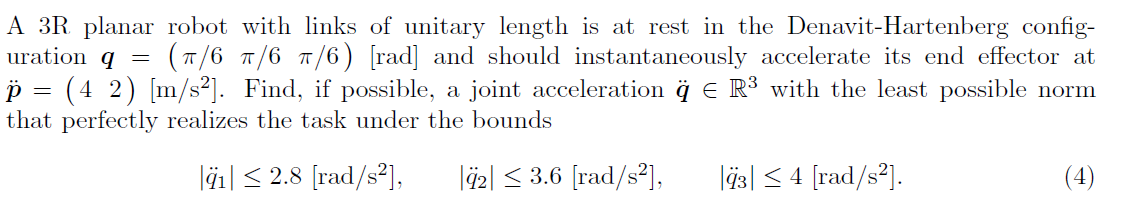

clear; clc;
V = [2.8,3.6,4] % Maximum acceleration constraints of joints
qnum = 3; %Number of joints
q = sym('q', [1 qnum]);
d = sym('d', [1 qnum]);
a = sym('a', [1 qnum]);

L = sym('l')

% a, alpha, 
R3Robot = [L 0 0 q(1);
           L 0 0 q(2);
           L 0 0 q(3)]
       
T0_EE = getTransformationMatrix(R3Robot)

% Calculate the Jacobian (Rotational)
config = 'RRR';
[Jp, Jo] = getJacobian(R3Robot,config)
%Jac = [Jp;Jo]
%Eliminate the zero rows, which represent the unused variables
Jp = Jp(~all(Jp == 0,2),:)

q1 = [pi/6, pi/6, pi/6]
J = subs(Jp, [q L], [q1 1])


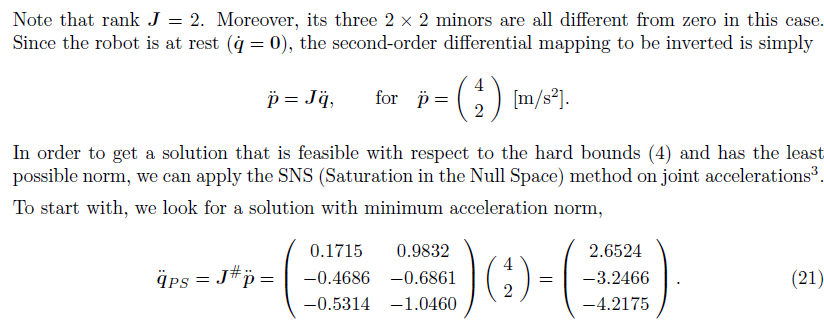

% SNS
xdot= [4,2].'
qdotPS = eval(pinv(J))*xdot
maxvalue = 1
qdotstar = qdotPS
qdot_sns = qdotPS
while maxvalue > 0
    [maxvalue, maxindex] = max(abs(qdotstar)-abs(V')) % The positive values are violating the limit. We take the highest one.
    if (maxvalue > 0) % if there is an exceeding value
        s = V(1)/qdotstar(maxindex)    
        %xdot_sns  = xdot - J(:,maxindex)* sign(qdotPS(maxindex))*V(maxindex)
        %Same as 
        xdot_sns  = xdot - abs(J(:,maxindex)*V(maxindex));
        Jtemp = J;
        Jtemp(:,maxindex) = [];
        qdot_components = eval(pinv(Jtemp)*xdot_sns).' 
        qdot_sns = [qdot_components(1:maxindex-1), V(maxindex), qdot_components(maxindex:end)]
        qdotstar = qdot_sns;
    else
        disp("[INFO] No values are exceeding the limits.")
        disp('Result:')
        qdotstar
    end
end
